# Ajuste de iluminación

La iluminación de una imagen está dada por la forma en la que el foco o fuente de energía están localizados. La iluminación debe de ser uniforme en toda la imagen para que todas las regiones se vean con la misma cantidad de brillo y que no se noten cambios de nivel de gris por sombras generadas de manera aleatoria.

En procesamiento de imágenes médicas, este aspecto es fundamental, ya que una mala iluminación puede ocultar estructuras relevantes o resaltar de manera incorrecta zonas que no presentan interés clínico. Por ejemplo, una iluminación irregular puede provocar que tejidos blandos parezcan más oscuros o que ciertas regiones óseas aparezcan con un nivel de brillo mayor al real, afectando la interpretación diagnóstica.

El ajuste de iluminación busca compensar estas variaciones, ya sea mediante técnicas de preprocesamiento que normalizan la intensidad de los píxeles, o a través del control físico de la fuente de luz durante la captura. Entre los métodos computacionales más utilizados se encuentran la ecualización del histograma, la corrección de fondo y las transformaciones de intensidad que ajustan la gama dinámica de la imagen.

En resumen, asegurar una iluminación homogénea no solo mejora la calidad visual de la imagen, sino que también garantiza que los análisis posteriores —como segmentación, filtrado o detección de bordes— se realicen sobre datos más confiables y representativos de la realidad anatómica.

La intensidad capturada en cada píxel puede escribirse como:  


$$f(x,y) = i(x,y) \cdot r(x,y)$$


donde:  

- $f(x,y)$ es la imagen observada en las coordenadas espaciales $(x,y)$.  

- $i(x,y)$ representa la **componente de iluminación**, asociada a la cantidad de energía que llega a cada punto de la escena.  

- $r(x,y)$ corresponde a la **reflectancia** de la superficie, es decir, la proporción de luz reflejada por los objetos.  

En este modelo, la iluminación $i(x,y)$ suele variar lentamente en la imagen, mientras que la reflectancia $r(x,y)$ contiene los cambios bruscos asociados a bordes, texturas o estructuras anatómicas.  

Así, la tarea de **ajuste de iluminación** consiste en minimizar el efecto de $i(x,y)$ para resaltar la información estructural de $r(x,y)$, de modo que la imagen procesada tenga una distribución de brillo más uniforme y represente mejor los detalles importantes.

X = imread("/home/erit/Desktop/Imagenes/misc/5.1.11.tiff");
disp(['Dimensiones: ' num2str(size(X))]);

Dimensiones: 256  256


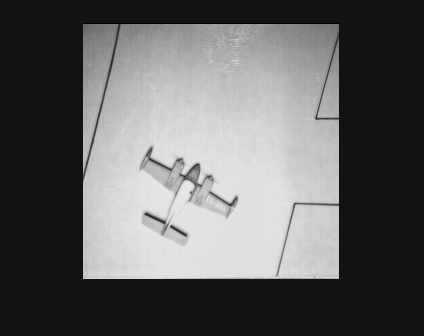

imshow(X);


Xnorm = reshape(normalize(double(X(:)),"range"),size(X));
disp(['mínimo: ' num2str(min(Xnorm(:)))]);

mínimo: 0


disp(['máximo: ' num2str(max(Xnorm(:)))]);

máximo: 1


En muchos casos, la iluminación no es uniforme en la imagen, sino que presenta variaciones sistemáticas a lo largo de la posición de los píxeles. Una manera de modelar este fenómeno es suponer que la componente de iluminación $i(x,y)$ puede aproximarse mediante una función polinómica en las coordenadas espaciales $x$ y $y$.  

Un modelo de tercer grado permite capturar variaciones suaves pero complejas en la iluminación y puede expresarse como:  


$$i(x,y) = a_0 + a_1x + a_2y + a_3x^2 + a_4xy + a_5y^2 + a_6x^3 + a_7x^2y + a_8xy^2 + a_9y^3$$


donde los coeficientes $a_0, a_1, \ldots, a_9$ definen la forma de la función de iluminación.  El ajuste de los coeficientes polinómicos puede hacerse mediante técnicas de regresión a partir de la intensidad de los píxeles, de modo que se estima la iluminación global y posteriormente se aplica una corrección al dividir o restar $i(x,y)$ de la imagen original.  